# **Part 1:Rotation**

clear all
clc

# Exercise 1.1

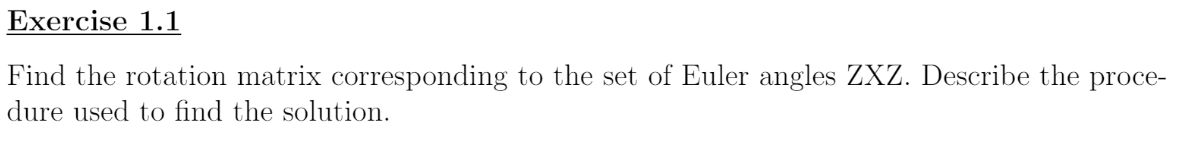

syms theta psi phi

rotation_z1=rotz(psi)
rotation_x=rotx(theta)
rotation_z2=rotz(phi)

Euler_ZXZ=rotation_z1*rotation_x*rotation_z2

# Exercise 1.2

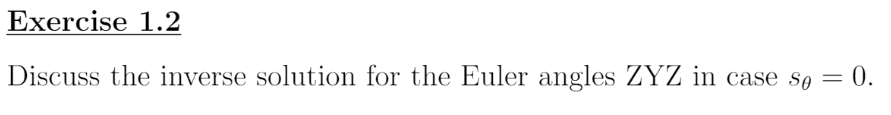

syms psi phi
theta=0
rotation_z1=rotz(psi)
rotation_y=roty(theta)
rotation_z2=rotz(phi)

Euler_ZYZ=simplify(rotation_z1*rotation_y*rotation_z2)
Inv_Euler_ZYZ=simplify(inv(Euler_ZYZ))


theta=pi
rotation_z1=rotz(psi)
rotation_y=roty(theta)
rotation_z2=rotz(phi)

Euler_ZYZ=simplify(rotation_z1*rotation_y*rotation_z2)
Inv_Euler_ZYZ=simplify(inv(Euler_ZYZ))


# Exercise 1.3

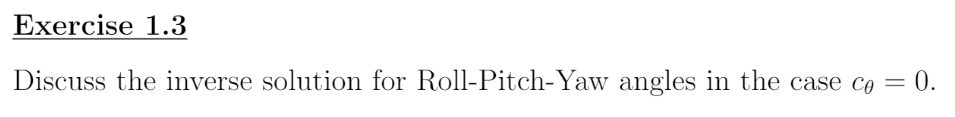

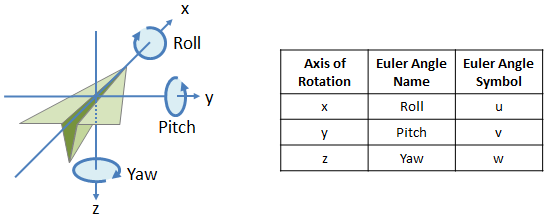

syms psi phi
theta=pi/2
rotation_x=rotx(psi)
rotation_y=roty(theta)
rotation_z=rotz(phi)

Euler_XYZ=simplify(rotation_x*rotation_y*rotation_z)
Inv_Euler_XYZ=simplify(inv(Euler_XYZ))

theta=-pi/2
rotation_x=rotx(psi)
rotation_y=roty(theta)
rotation_z=rotz(phi)

Euler_XYZ=simplify(rotation_x*rotation_y*rotation_z)
Inv_Euler_XYZ=simplify(inv(Euler_XYZ))

# Exercise 1.4

# Exercise 1.5

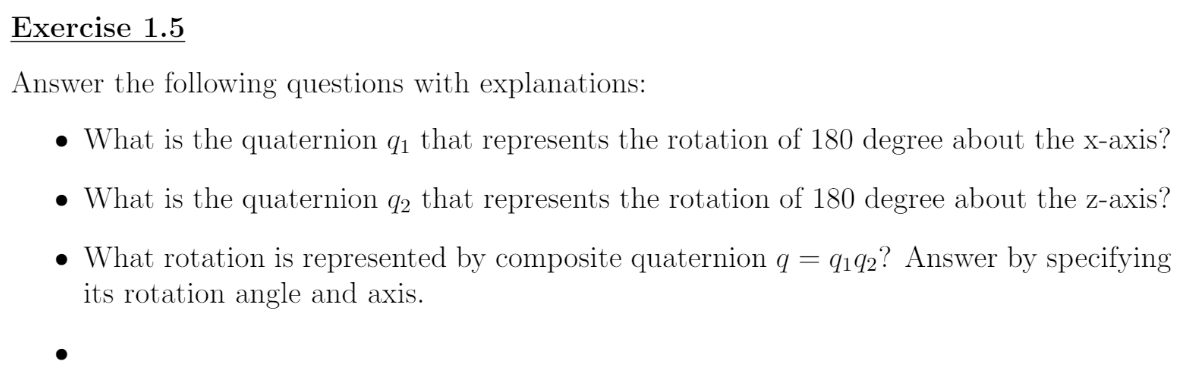

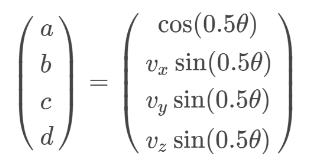

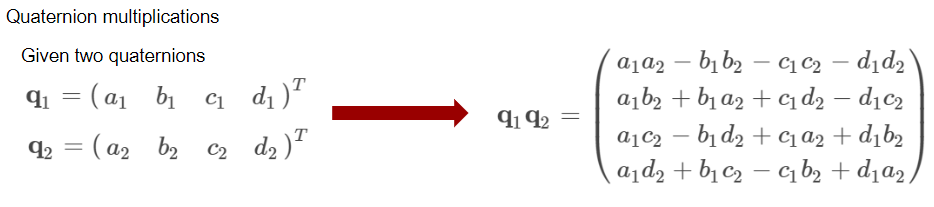

vx = 1;
vy = 0;
vz = 0;
theta = deg2rad(180);

q1 = [cos(0.5*theta);vx*sin(0.5*theta);vy*sin(0.5*theta);vz*sin(0.5*theta)];
q1
%%%%%%%%
vx = 0;
vy = 0;
vz = 1;
theta = deg2rad(180);

q2 = [cos(0.5*theta);vx*sin(0.5*theta);vy*sin(0.5*theta);vz*sin(0.5*theta)];
q2
%%%%%%%%
q = qMultiply(q1,q2);
q


# Exercise 1.6

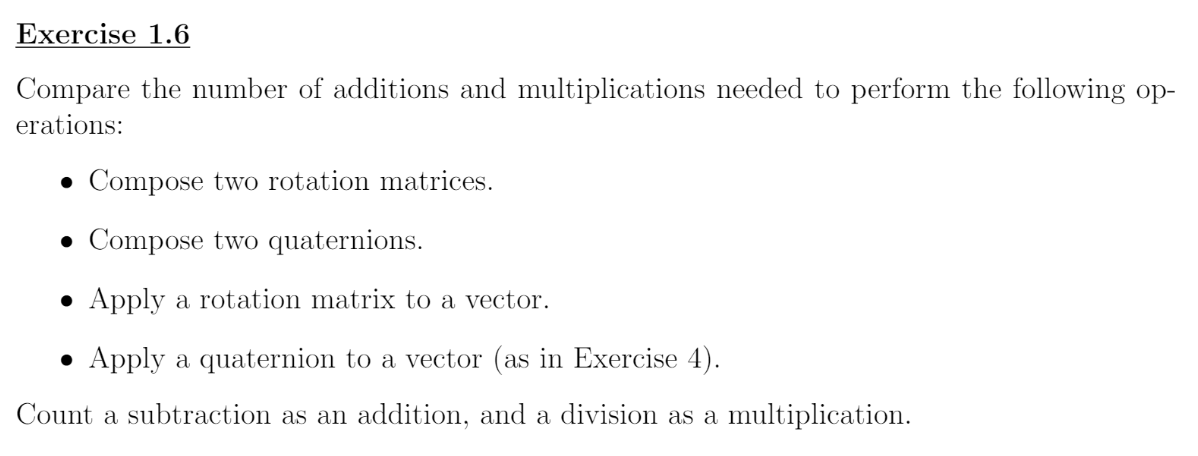

% Compose two rotation matrices
% ???????
% ???????

% Compose two quaternions
% has 16 multiplications 
% and 12 additions

syms theta alpha beta phi
zrot=[cos(phi) -sin(phi) 0;sin(phi) cos(phi) 0;0 0 1]% rotation around z

xrot=[1 0 0;0 cos(alpha) -sin(alpha);0 sin(alpha) cos(alpha)]% rotation around x
zrot*xrot(:,1)
zrot*xrot(:,2)
zrot*xrot(:,3)
xrot*yrot


# Appendix

function q = qMultiply(q1,q2)
%UNTITLED Summary of this function goes here
%   Detailed explanation goes here
a1 = q1(1);
b1 = q1(2);
c1 = q1(3);
d1 = q1(4);
a2 = q2(1);
b2 = q2(2);
c2 = q2(3);
d2 = q2(4);
q = [a1*a2-b1*b2-c1*c2-d1*d2;
    a1*b2+b1*a2+c1*d2-d1*c2;
    a1*c2-b1*d2+c1*a2+d1*b2;
    a1*d2+b1*c2-c1*b2+d1*a2];
end

function [rotmtx] = rotx(angle)
% return the rotation matrix around x axis
% angle: degree
rotmtx = [1, 0, 0; 0, cos(angle), -sin(angle); 0, sin(angle), cos(angle)];
end

function [rotmtx] = roty(angle)
% return the rotation matrix around x axis
% angle: degree
rotmtx = [cos(angle), 0, sin(angle); 0, 1, 0; -sin(angle), 0, cos(angle)];
end

function [rotmtx] = rotz(angle)
% return the rotation matrix around x axis
% angle: degree
rotmtx = [cos(angle), -sin(angle), 0; sin(angle), cos(angle), 0; 0, 0, 1];
end

